# Cleaned-Up Square Conducting Analysis

Anil and Samyoung

[square_accel, square_gyro] = parsePowerSenseData_1('anil_perfect_square.csv');

% data grabbing
times = square_accel(:,1);                % grab times column
times = times-times(1);                   % center unex times
x_accel_square = square_accel(1:end,2);   % grab xaccel
z_accel_square = square_accel(1:end,4);   % grab yaccel

num = 8;
h = ones(1, num)./num;    % define convolution shape

% double moving average on z data
zacc = conv(z_accel_square, h);
zacc = zacc(1:end-length(h)+1);
zacc = conv(zacc, h);
zacc = zacc(1:end-length(h)+1);
untouchedz = zacc;

% double moving average on x data
xacc = conv(x_accel_square, h);
xacc = xacc(1:end-length(h)+1);
xacc = conv(xacc, h);
xacc = xacc(1:end-length(h)+1);

% z acceleration beat analysis
% beat de-fuzzing
for i = 1 : size(zacc)-4
    if(abs((zacc(i)- 9.81) < 1) && (abs((zacc(i + 2)- 9.81))< 1))
        zacc(i) = 9.81;
    end
end

% initialize some arrays
beatOne = [];
beatThree = [];

% Loop through all zaccels, find ones and threes
for i = 3 : size(zacc)-4
    % beat one checker
    if((zacc(i)== 9.81) && (zacc(i-1)- 9.81 >0) && (zacc(i+ 1)== 9.81))
        beatOne = cat(1, beatOne, i);
    end
    
    % beat three checker
    if((zacc(i)== 9.81) && (zacc(i+1)- 9.81 >0) && (zacc(i- 1)== 9.81))
         beatThree = cat(1, beatThree, i);
    end
end

% Use xaccel to find beat two
binarySignal = xacc < -2;
leadingEdges2 = find(diff(binarySignal) >= 1);
beatTwo = leadingEdges2;

% uses indexes to find timestamps
beatOneTimes = times(beatOne)

beatOneTimes =     5.3806
    8.0209
   10.6212
   13.2615
   15.9218
   18.6821
   21.3224
   24.0027
   26.6630
   29.2433


beatTwoTimes = times(beatTwo)

beatTwoTimes =     5.5606
    6.4407
    8.2009
    9.1410
   10.8412
   11.7413
   13.5215
   14.3816
   16.1218
   17.1019


beatThreeTimes = times(beatThree)

beatThreeTimes =     3.2404
    6.8008
    9.4211
   12.0214
   14.6617
   17.4820
   20.0623
   22.7626
   25.4429
   28.0232


% % find beat lengths
% onetotwo = beatTwoTimes-beatOneTimes;
% twotothree = beatThreeTimes-beatTwoTimes;

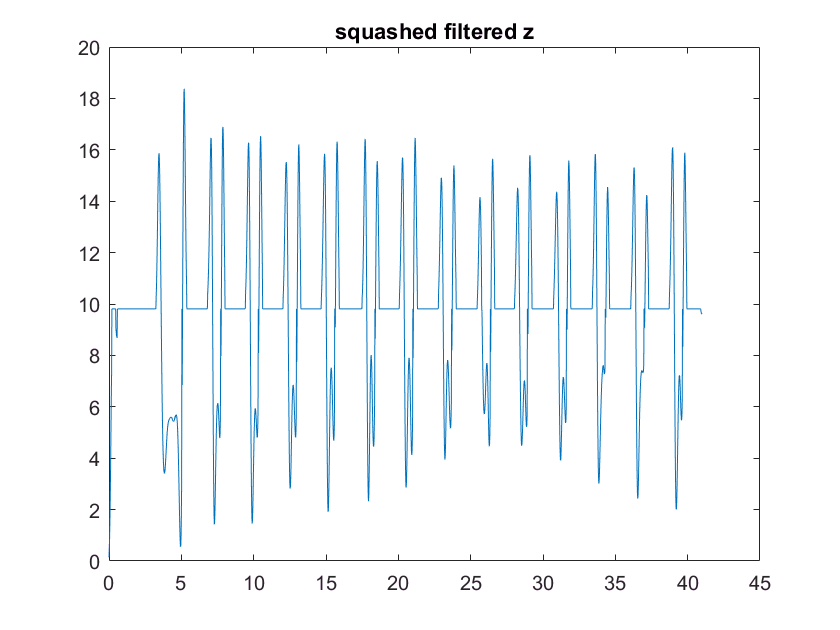

% visualize all data
plot(times,zacc)
title('squashed filtered z')

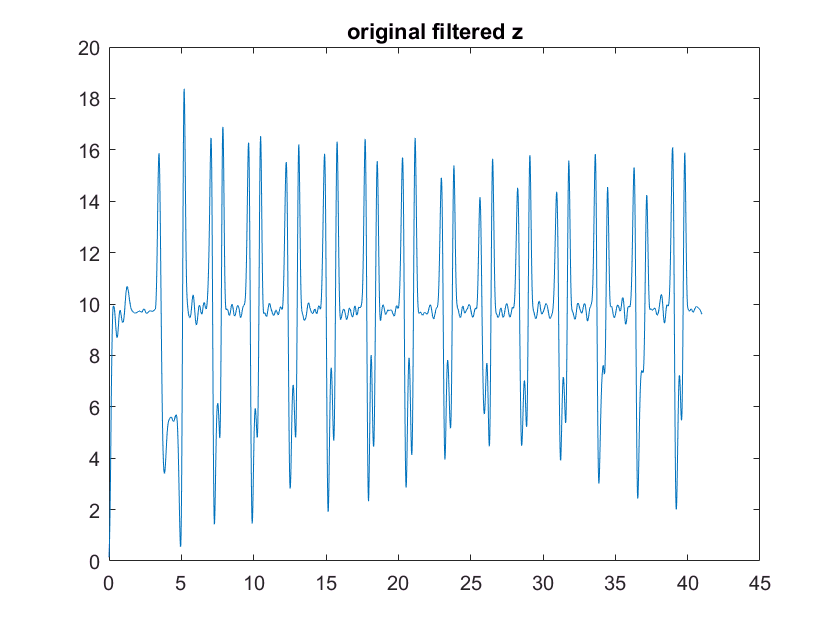

plot(times,untouchedz)
title('original filtered z')

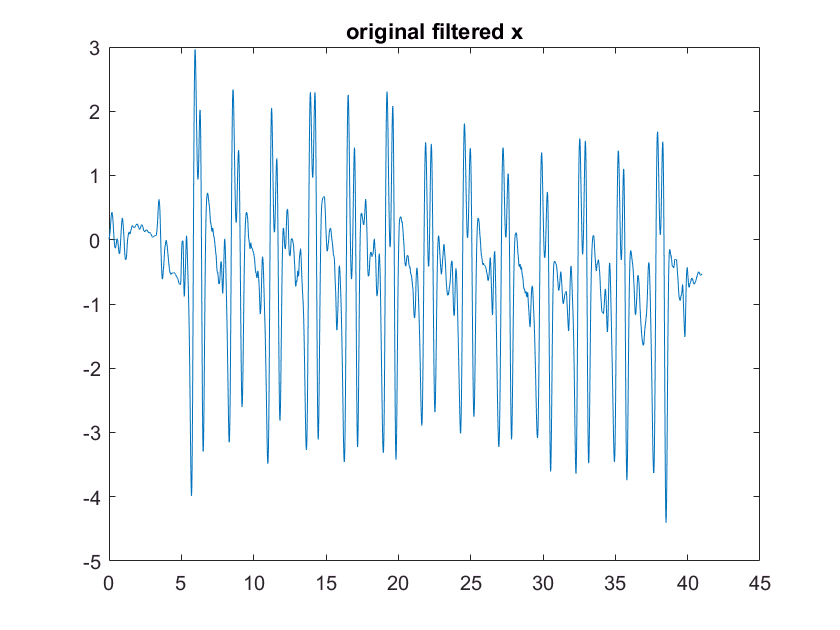

plot(times,xacc)
title('original filtered x')